# 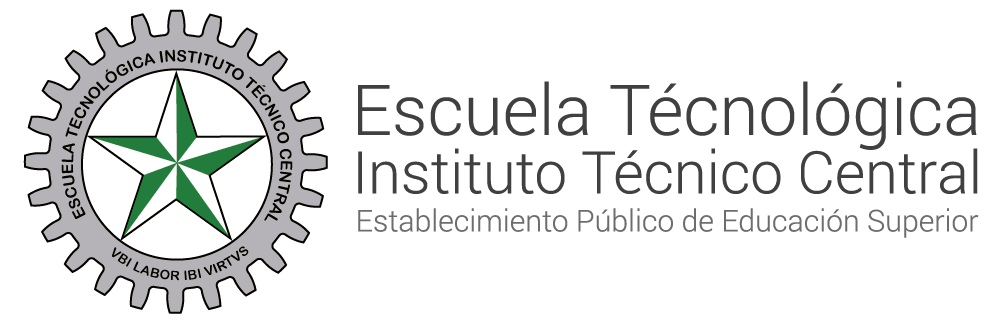

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones en diferencias**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

**CoAutores: Elberth Dirjhampher Ariza Ferreira, Jesús Manuel Pardo Gonzalez**

# Metodología

Para desarrollar los ejercicios relacionados con la transformada Z, se seguirá el siguiente enfoque metodológico:

Primero, se resolverá cada ejercicio de forma **manual**, es decir, aplicando los procedimientos matemáticos paso a paso, utilizando ecuaciones escritas y desarrollos teóricos.

Posteriormente, se implementará un **algoritmo **en MATLAB que permita verificar y validar los resultados obtenidos, así como entender el uso de las funciones propias del software para este tipo de análisis.

De esta manera, se busca no solo obtener la solución correcta, sino también comprender a fondo el procedimiento matemático y su aplicación computacional, fortaleciendo tanto la parte teórica como práctica.

**Encuentre la transformada z para la variable de salida de:** 

# Solución Aplicando Procedimientos Matematicos:

## Paso 1

Antes de iniciar con la solución del ejercicio, es importante **identificar el tipo de ecuación** que se está abordando. En este caso, se trata de una **ecuación en diferencias**, para resolver este tipo de ecuaciones, se recurre a la **Transformada Z**, por motivos que necesitamos pasarla al dominio Z.

Es fundamental tener en cuenta que, al aplicar la Transformada Z, se requiere el conocimiento y manejo de **tablas de transformadas Z** , las cuales son herramientas clave para transformar correctamente cada término de la ecuación.

A continuación, se muestra una imagen de referencia que resume dichas propiedades, las cuales serán utilizadas en el proceso de resolución paso a paso.

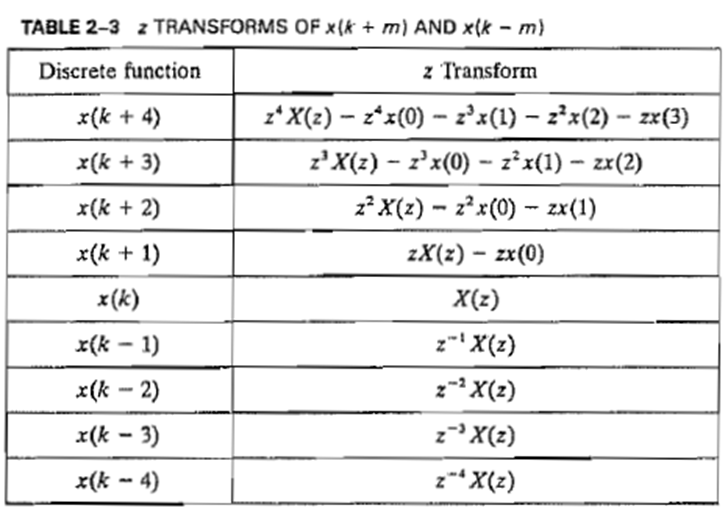

## Paso 2

Una vez revisadas las tablas de la Transformada Z, procedemos a identificar las variables y términos presentes en la ecuación en diferencias con el fin de sustituirlos correctamente mediante las equivalencias de la tabla.

A partir del análisis, se determinan qué términos pueden ser transformados utilizando dichas propiedades. El procedimiento se realiza de la siguiente manera:


$$y\;\left(k+2\right)\;=\;\;z^2 Y\left(z\right)-z^2 y\left(0\right)-\textrm{zy}\left(1\right)$$



$$x\;\left(k\right)\;=\;\;Y\left(z\right)$$



$$u\;\left(k\right)\;=\;U\left(z\right)$$


## Paso 3

Después de identificar y transformar cada componente, se reemplazan los términos en la ecuación utilizando las expresiones obtenidas a través de la Transformada Z. Posteriormente, se procede a reorganizar y unificar la ecuación en el dominio Z, quedando de la siguiente forma:


$$z^2 Y\left(z\right)-z^2 y\left(0\right)-\mathrm{zy}\left(1\right)-Y\left(z\right)=\;U\left(z\right)$$
 

## Paso 4

Una vez obtenida la ecuación en el dominio Z, procedemos a sustituir las condiciones iniciales que fueron proporcionadas anteriormente, ya que estas son fundamentales para completar la solución del sistema.

- **y(0) = 1**

- **y(1) = 0**

Al incorporar estos valores en la ecuación transformada, se obtiene la siguiente expresión:


$$z^2 Y\left(z\right)-z^2 \left(1\right)-z\left(0\right)-Y\left(z\right)=\;U\left(z\right)$$



$$z^2 Y\left(z\right)-z^2 -Y\left(z\right)=\;U\left(z\right)$$


## Paso 5

Finalmente, una vez sustituimos las condiciones iniciales en la ecuación en el dominio Z, **procedemos a despejar Y(z)**, que representa la respuesta del sistema en ese mismo dominio.

Para realizar este despeje, podemos aplicar **factor común**, lo cual nos permite reorganizar la ecuación y aislar Y(z) de forma más sencilla y ordenada.


$$Y\left(z\right)\left\lbrack z^2 -1\right\rbrack -z^2 =\;U\left(z\right)$$



$$Y\left(z\right)\left\lbrack z^2 -1\right\rbrack =\;U\left(z\right)+z^2$$



$$Y\left(z\right)=\frac{U\left(z\right)+z^2 }{z^2 -1}$$


Por ultimo tomamos U(z) como una señal escalon, la cual se representa como $\frac{Z}{Z-1}$ , y la reemplazamos en nuestra ecuacion final.

 
$$Y\left(z\right)=\frac{U\left(z\right)+z^2 }{z^2 -1}\;\;\;\longrightarrow \;Y\left(z\right)=\frac{\frac{z}{z-1}+z^2 }{z^2 -1}$$


# Solución con Algoritmo Matlab

Una vez finalizado el procedimiento de forma manual o matemática, damos paso a la siguiente parte de nuestra metodología: la implementación del **algoritmo** en MATLAB, el cual nos permite verificar los resultados obtenidos manualmente y, además, entender cómo se pueden resolver este tipo de ejercicios por medio de esta herramienta.

En esta etapa, cada línea del código será explicada detalladamente:

clc; clear;

- `clc`: Limpia la ventana de comandos para comenzar con una pantalla limpia.

- `clear`: Elimina todas las variables del espacio de trabajo para evitar conflictos con variables previas o tablas que se hayan creado.

syms z Y U

- `syms`: Es una libreria que nos permite declarar lo que son varibles (en este caso tenemos Z, Y y U).

- `z`: Es la variable del dominio de la transformada Z.

- `Y`: Representa la transformada Z de la salida `y[k]`, es decir, `Y(z)`.

- `U`: Representa la transformada Z de la entrada `u[k]`, es decir, `U(z)`.

**Nota: **Si la salida fuera representada en x[k], seria syms z X U , cambia y depende de la ecuacion que estemos trabajando. 

y0 = 1;
y1 = 0; 

Se definen las condiciones iniciales del sistema, que nos suministraron.

Yz = z^2*Y - z^2*y0 - z*y1 - Y; 

Aquí se aplica la Transformada Z a cada término de la ecuación:

- La transformada Z de `y[k+2]` es: `z^2·Y(z) - z^2·y(0) - z*y(1)` 

- La transformada Z de `y[k]` es simplemente `Y(z) (Recordemos que al principio del codigo con ayuda de la libreria, estipulamos que Y, es y[k] )`.

- Por lo tanto, el lado izquierdo queda: `z^2·Y(z) - z^2·y(0) - z*y(1) - Y(z)`.

Este paso convierte la ecuación en diferencias en una ecuación algebraica en el dominio Z.

U = z/(z - 1);

En este caso vamos a tomar que la señal de entrada U(z) corresponde a una **señal escalon**, que se representa como $\frac{Z}{z-1}$.

eq = Yz == U;

Aqui lo que se realiza es igualar la ecuacion anterior con la entrada que es u[k] (recordemos U(z) fue tomada como una **señal escalon**) y al mismo tiempo la estamos guardando en una nuev variable llamada eq, tambien podiramos escribirla de la siguiente manera:

eq = z^2*Y - z^2*y0 - z*y1 - Y == U ;

Yz_sol = solve(eq, Y);

Gracias a la funcion **solve** podemos despejar la transformada Y(z) de la ecuacion, es decir, como se realizo de forma matematica uilizando el factor comun, para esto tomamos la ecuacion que vamos a realizar el cambio y separando con una coma, que valor queremos despejar, y por ultimo lo guradamos en Yz_sol.

% Mostramos la expresión final de Y(z)
disp('Transformada Z de Y(z):');

Transformada Z de Y(z):


(Yz_sol)

$$Yz\_sol = \frac{\frac{z}{z-1}+z^{2}}{z^{2}-1}$$